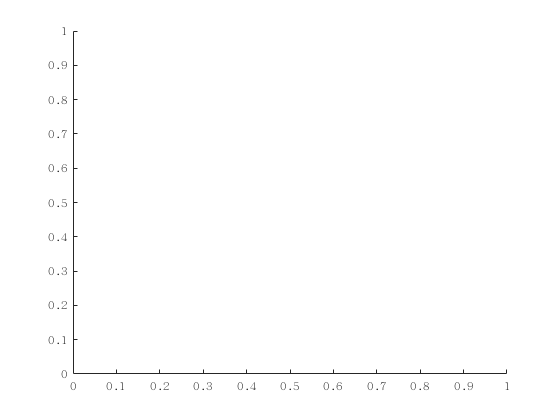

%clear all
hold on

p0=[10;15;20];
p1=[15;10;10];
[L1 orth1]=point2line(p0,p1);
p0=[20;5;0];
p1=[5;20;30];
[L2 orth2]=point2line(p0,p1);

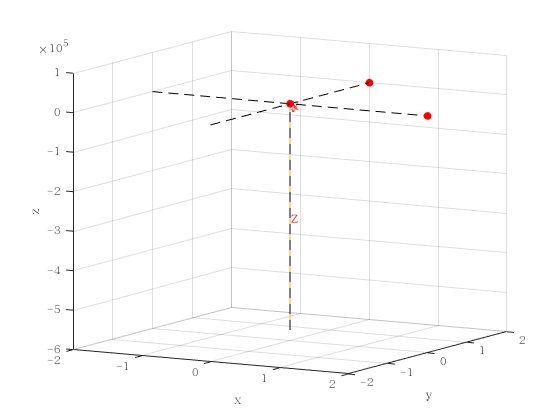


U=eye(3);
W0=[1 -1;1 1];
[p0 p1]=line2point(U,W0);
line3([p0 p1]);

%U=expm(toCross([0;0;1]*pi/2)); %绕[0;0;1]逆时针旋转pi/2
de=44.9999;W=[cosd(de) -sind(de);sind(de) cosd(de)]*W0;
[p0 p1]=line2point(U,W);
line3([p0 p1]);

de=-de;W=[cosd(de) -sind(de);sind(de) cosd(de)]*W0;
[p0 p1]=line2point(U,W);
line3([p0 p1]);

figureAxis;

p1=[10;10;10];p2=[50;14;18];
for i=1:10000
a=randn(1);b=1-a;
p3=a*p1+b*p2;
a=randn(1);b=1-a;
p4=a*p1+b*p2;
[L1 orth1]=point2line(p3,p4);
n=L1.n;v=L1.v;
a=randn(1);b=1-a;
p3=a*p1+b*p2;
a=randn(1);b=1-a;
p4=a*p1+b*p2;
[L1 orth1]=point2line(p3,p4);
n_=L1.n;v_=L1.v;
err_i(i)=norm([cross(v,n)/(v'*v)-cross(v_,n_)/(v_'*v_);cross(v,v_)]);
end
norm(err_i)

ans =       8.39396714419176e-11

line=line_w{6};
[L orth]=point2line(line.sP,line.eP)